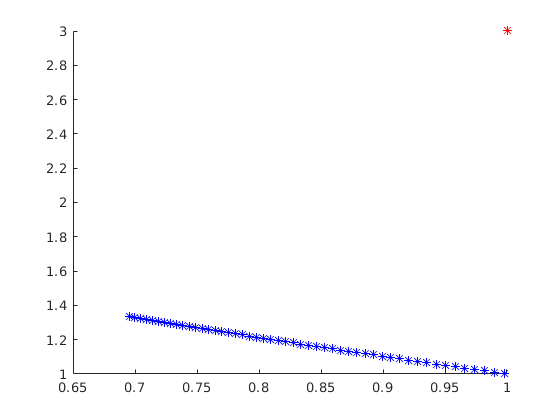

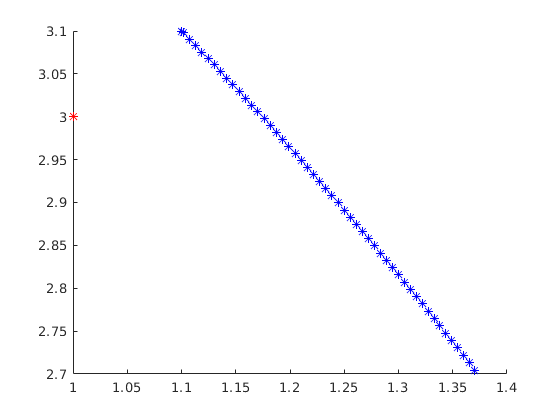

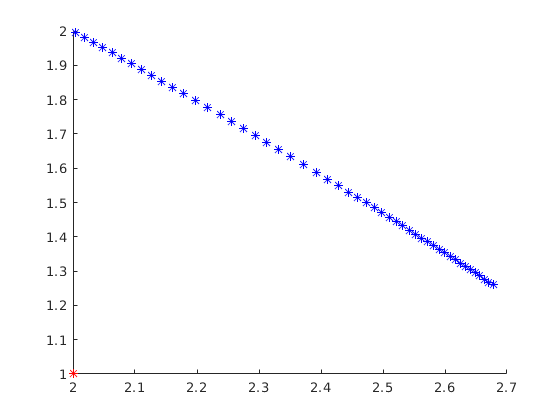

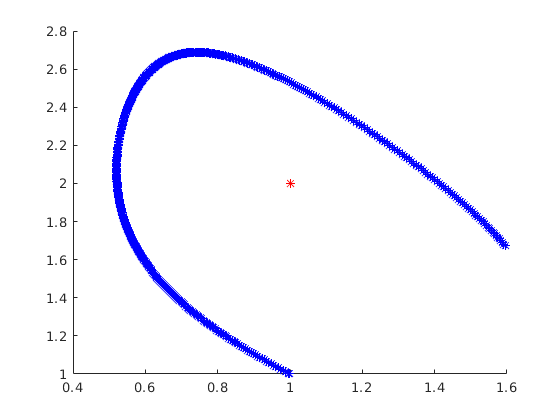

% establish values
s0 = [1, 1; 1.1, 3.1; 2, 2; 1, 1]; % initial conditions
params = [1, 3; 1, 3; 2, 2; 1, 2]; % parameters for state functions
steps = [50, 50, 50, 500];

% solve each situation
for i = 1:size(s0, 1)
    % set up initial conditions for problem
    s = s0(i, :);
    param = params(i, :);
    n = steps(i);
    tau = 1e-3;
    err = 1e-12;
    % reset accumulators
    x = [];
    y = [];
    t = 0;
    % find solution for conditions given
    for j = 1:n
        [s, t, tau] = rka(s, t, tau, err, 'brussf', param);
        x(j) = s(1);
        y(j) = s(2);
    end
    % get steady state data
    A = param(1);
    B = param(2);
    x_steady = A;
    y_steady = B/A;
    % plot solution in xy and steady state data
    figure(i)
    hold on
    plot(x, y, 'b*')
    plot(x_steady, y_steady, 'r*')
    hold off
end